% mikexcohen@gmail.com

## amplitude non-stationarity

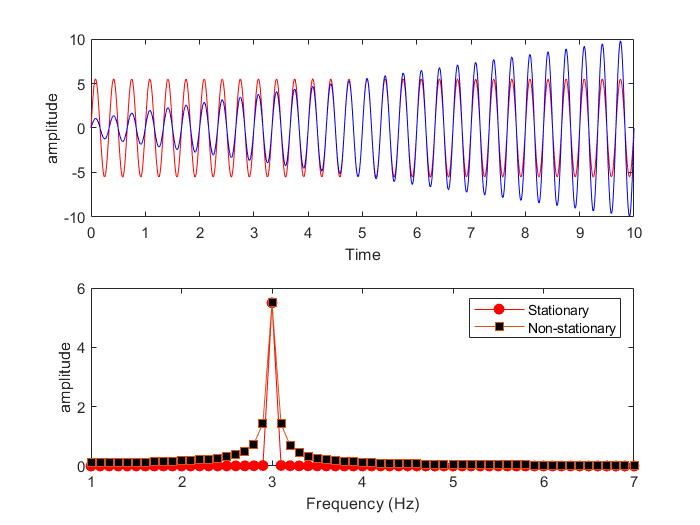

srate = 1000;
t = 0:1/srate:10;
n = length(t);
f = 3; % frequency in Hz

% sine wave with time-increasing amplitude
ampl1 = linspace(1,10,n);
% ampl1 = abs(interp1(linspace(t(1),t(end),10),10*rand(1,10),t,'spline'));
ampl2 = mean(ampl1);

signal1 = ampl1 .* sin(2*pi*f*t);
signal2 = ampl2 .* sin(2*pi*f*t);


signal1X = fft(signal1)/n;
signal2X = fft(signal2)/n;
hz = linspace(0,srate/2,floor(n/2)+1);

figure(1), clf
subplot(211)
plot(t,signal2,'r'), hold on
plot(t,signal1, 'bl')
xlabel('Time'), ylabel('amplitude')

subplot(212)
plot(hz,2*abs(signal2X(1:length(hz))),'ro-','markerface','r')
hold on
plot(hz,2*abs(signal1X(1:length(hz))),'s-','markerface','k')

xlabel('Frequency (Hz)'), ylabel('amplitude')
set(gca,'xlim',[1 7])
legend({'Stationary';'Non-stationary'})

## frequency non-stationarity

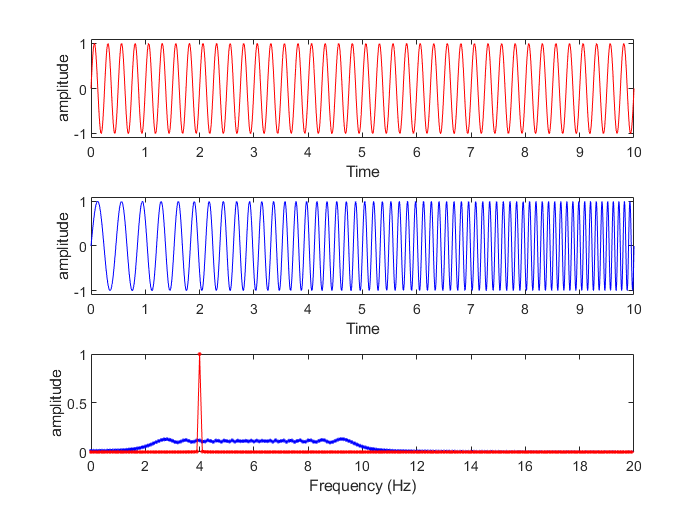

f  = [2 10];
ff = linspace(f(1),mean(f),n);
signal1 = sin(2*pi.*ff.*t);
signal2 = sin(2*pi.*mean(ff).*t);


signal1X = fft(signal1)/n;
signal2X = fft(signal2)/n;
hz = linspace(0,srate/2,floor(n/2));

figure(2), clf

subplot(312)
plot(t,signal1, 'bl')
xlabel('Time'), ylabel('amplitude')
set(gca,'ylim',[-1.1 1.1])

subplot(311)
plot(t,signal2,'r')
xlabel('Time'), ylabel('amplitude')
set(gca,'ylim',[-1.1 1.1])

subplot(313)
plot(hz,2*abs(signal1X(1:length(hz))),'bl.-'), hold on
plot(hz,2*abs(signal2X(1:length(hz))),'r.-')
xlabel('Frequency (Hz)'), ylabel('amplitude')
set(gca,'xlim',[0 20])

## sharp transitions

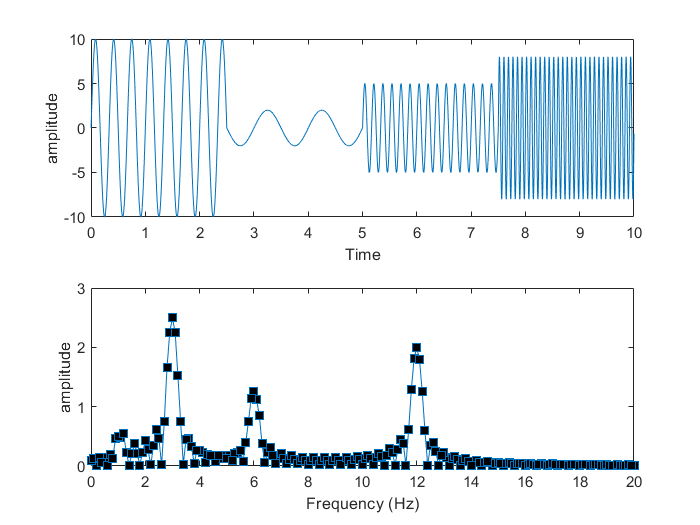

a = [10 2 5 8];
f = [3 1 6 12];

timechunks = round(linspace(1,n,length(a)+1));

signal = 0;
for i=1:length(a)
    signal = cat(2,signal,a(i)* sin(2*pi*f(i)*t(timechunks(i):timechunks(i+1)-1) ));
end

signalX = fft(signal)/n;
hz = linspace(0,srate/2,floor(n/2)+1);

figure(3), clf
subplot(211)
plot(t,signal)
xlabel('Time'), ylabel('amplitude')

subplot(212)
plot(hz,2*abs(signalX(1:length(hz))),'s-','markerface','k')
xlabel('Frequency (Hz)'), ylabel('amplitude')
set(gca,'xlim',[0 20])

## edges and edge artifacts

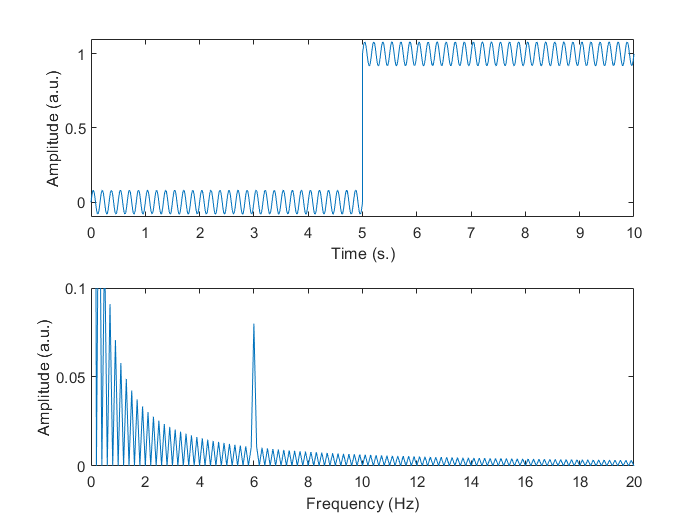

%x = (linspace(0,1,n)>.5)+0; % +0 converts from boolean to number
 x = x + .08*sin(2*pi*6*t);

% plot
figure(4), clf
subplot(211)
plot(t,x)
set(gca,'ylim',[-.1 1.1])
xlabel('Time (s.)'), ylabel('Amplitude (a.u.)')

subplot(212)
xX = fft(x)/n;
plot(hz,2*abs(xX(1:length(hz))))
set(gca,'xlim',[0 20],'ylim',[0 .1])
xlabel('Frequency (Hz)'), ylabel('Amplitude (a.u.)')